# **Case B: Econometrics. Regression with matrices or non-linear optimization **

In this notebook, we will consider a linear model. We will: 

- Estimate parameters using the simple covariance-variance formula with a single regressor, 

- Estimate parameters using matrices, 

- Estimate parameters using matrices with two regressors, 

- Visualize OLS in 3D, 

- Estimate parameters using numerical optimization, 

- Estimate a model with numerical optimization which cannot be estimated with OLS. 

clc; clear all; 
rng('default'); % seeding the random number generator 

## **1: Ordinary Least Squares (OLS) with one continuous regressor**

Consider the following regression model, where $y_i$ is explained by a constant and a single continuous regressor, $x_i$. 


$$y_i = \beta_0 + \beta_1 x_i + u_i, \quad u_i \sim \mathcal{N}(0,\sigma^2).$$


We start by choosing the parameters

N = 100; % sample size
beta_0 = 1; 
beta_1 = -0.5; 
sigma_u = 1; 
sigma_x = 5; 

Let us start by simulating a dataset and then see if we can estimate back the parameters. To do so, we will need to choose how to draw $x_i$ (even though the OLS estimator does not rely on other assumptions than the *rank condition*, which in this case amounts to $x_i$ not being constant). Let us draw $x_i$ as independent normals with std.dev. of `sigma_x` = 5 (the higher `sigma_x` is relative to `sigma_u`, the more precise will be the estimates - you can change these and look at the graph below to see visually why that is). 

u = sigma_u*randn(N,1); 
x = sigma_x*randn(N,1); 
y = beta_0 + beta_1*x + u; 

Now we can create $y_i$ and show a scatter plot of $y_i$ against $x_i$ 

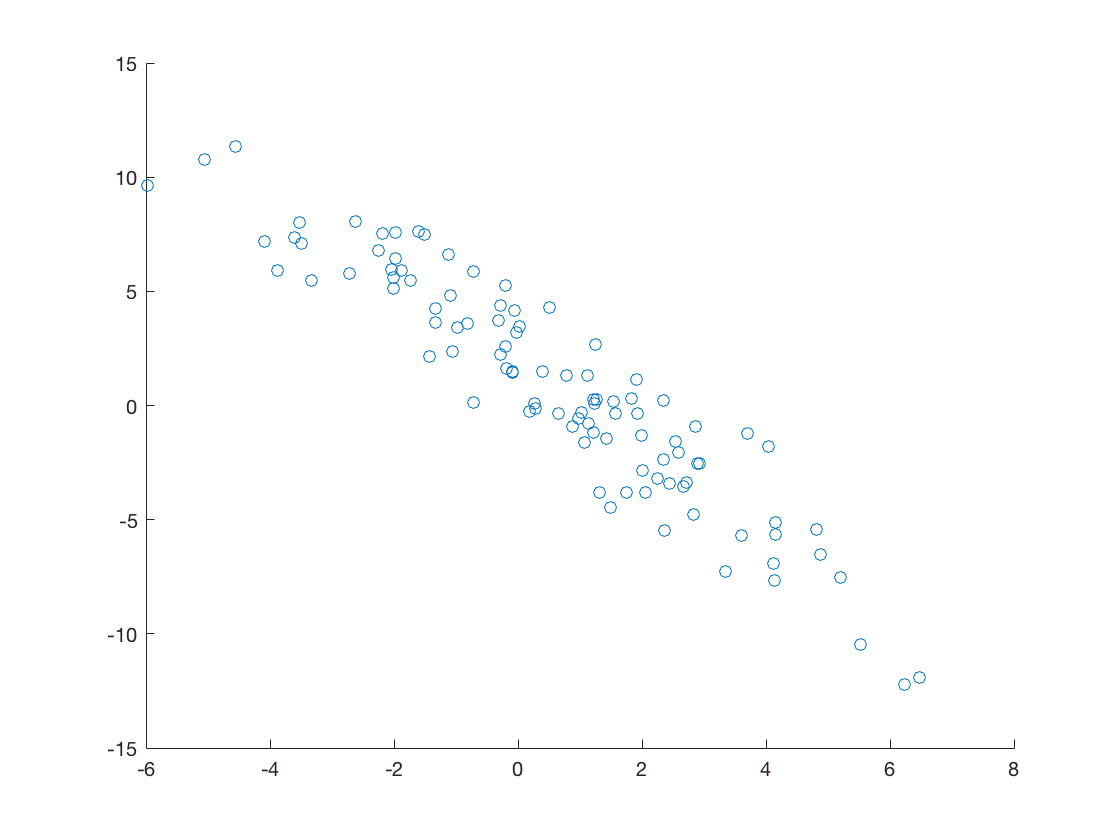

scatter(y,x); 

In the univariate case, we know that we can find the estimates, $(\hat{\beta}_0,\hat{\beta_1)$, as 


$$\hat{\beta}_1 = \frac{\widehat{\mathrm{Cov}}(y,x)}{\hat{\sigma}_x^2},\quad 
\hat{\beta}_0 = \bar{y} - \hat{\beta}_1 \bar{x}.$$


We estimate the components by $\hat{\sigma}_x^2 = \frac{1}{N-1} \sum_{i=1}^N (x_i-\bar{x})^2$ and  $\widehat{\mathrm{Cov}}(y,x) = \frac{1}{N-1} \sum_{i=1}^N (y_i-\bar{y})(x_i-\bar{x})$, and where $\bar{y},\bar{x}$ denote the means of $y,x$ respectively. 

var_x     = 1/(N-1) * sum((x-mean(x)).^2); % estimated Var(x)
cov_y_x   = 1/(N-1) * sum((y-mean(y)) .* (x-mean(x))); % estimated Cov(y,x)
betahat_1 = cov_y_x / var_x

betahat_1 = -0.4820

betahat_0 = mean(y) - betahat_1 * mean(x)

betahat_0 = 0.9801

Next, let's compare the fitted values to the actual values: 

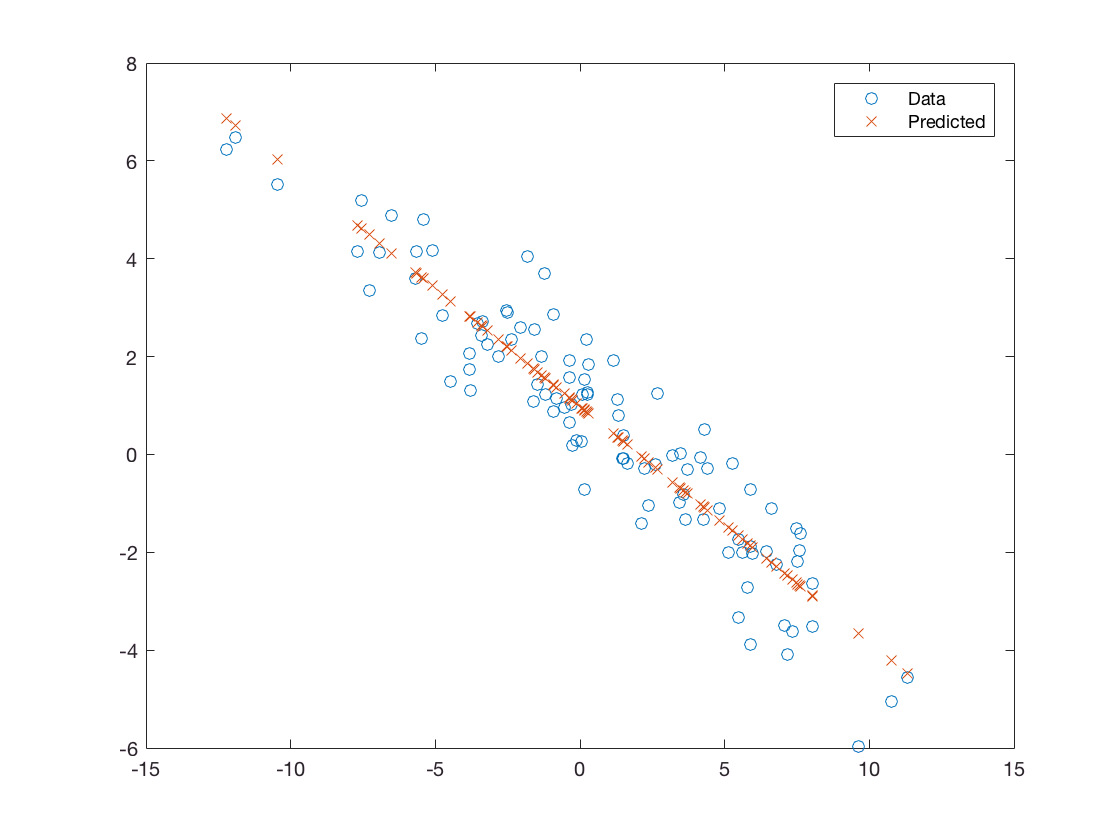

yhat = betahat_0 + betahat_1*x; 
plot(x,y,'o',x,yhat,'x'); legend('Data','Predicted'); 

## 2: Matrix version

In this section, we will estimate the same parameters as above but using matrices. Let 


$$\mathbf{y} = 
\pmatrix{
y_1 \cr
y_2 \cr 
\vdots \cr 
y_N 
}
, \quad 
\mathbf{X} = 
\pmatrix{
1 & x_1 \cr 
1 & x_2 \cr 
\vdots & \vdots \cr 
1 & x_N 
}$$


The variable, `y`, already takes this form, so we just need to create the matrix `X` similar to $\mathbf{X}$: 

X = [ones(N,1),x]; 

We then know that the OLS estimator can be obtained as 


$$\pmatrix{\hat{\beta}_0 \cr \hat{\beta}_1}
= (\mathbf{X}' \mathbf{X})^{-1} \mathbf{X}' \mathbf{y}.$$


In Matlab, this can simply be written as `(X'*X)^-1 * X'*y`, or alternatively in this way:

betahat = (X'*X) \ X'*y

betahat =     0.9801
   -0.4820


Behind the scenes, Matlab does something else when we use the "backslash" operator than when we use the inverse operator, which is both faster and less prone to roundoff errors. See more details about this in the very bottom of the notebook. 

## 3: OLS with two continuous regressors

Now, we turn to the model with two regressors, 


$$y_i = \beta_0 + \beta_1 x_{1i} + \beta_2 x_{2i} + u_i,$$


where $x_{1i}\ \sim \mathcal{N}(0,\sigma_{x1}^2), x_{2i}\ \sim \mathcal{N}(0,\sigma_{x2}^2), u_i \sim \mathcal{N}(0,\sigma_u^2).$

% Parameters 
N = 100; 

sigma_x1 = 5; 
sigma_x2 = 4; 
sigma_u = 4; 

beta_1 = -0.5; 
beta_2 = 0.5; 
beta_0 = 1; 
beta = [beta_0; beta_1 ; beta_2]; 

This time, `X` will be $N \times 3$, while `y` and `u` will both again be $N\times 1 $ vectors. 

% Simulating data
x1 = sigma_x1 * randn(N,1); 
x2 = sigma_x2 * randn(N,1); 
X = [ones(N,1), x1, x2];
u = sigma_u * randn(N,1); 

y = X*beta + u; 

The estimation equation is the same as with just one continuous regressor: 


$$\hat{\bf{\beta}}
= (\mathbf{X}' \mathbf{X})^{-1} \mathbf{X}' \mathbf{y}.$$


betahat = (X'*X)\X'*y

betahat =     1.0243
   -0.4793
    0.4831


As you can see, once variables are read in as columns in `X`, estimation is the same no matter how many variables are included. 

## 4: Plotting the OLS predictions in 3D

As with a single continuous regressor, we can create the predicted values of $y_i$ when there are two: 

yhat = X*betahat;  

Below, we will plot `yhat` against `x1` and `x2`, i.e. in three dimensions. Since this is a point-cloud in 3D, we will use `plot3`. 

figure(); 
hold on; % ... we want to add another plot 
p = plot3(x1,x2,y,'o',x1,x2,yhat,'x','LineWidth',1.5); 

Moreover, we will plot the predicted value of `yhat` over a 2-dimensional grid of (`x1`, `x2`) with 10 grid points in each direction from the minimum to the maximum. Since this is a "surface" in 3D, we will use `surf`. 

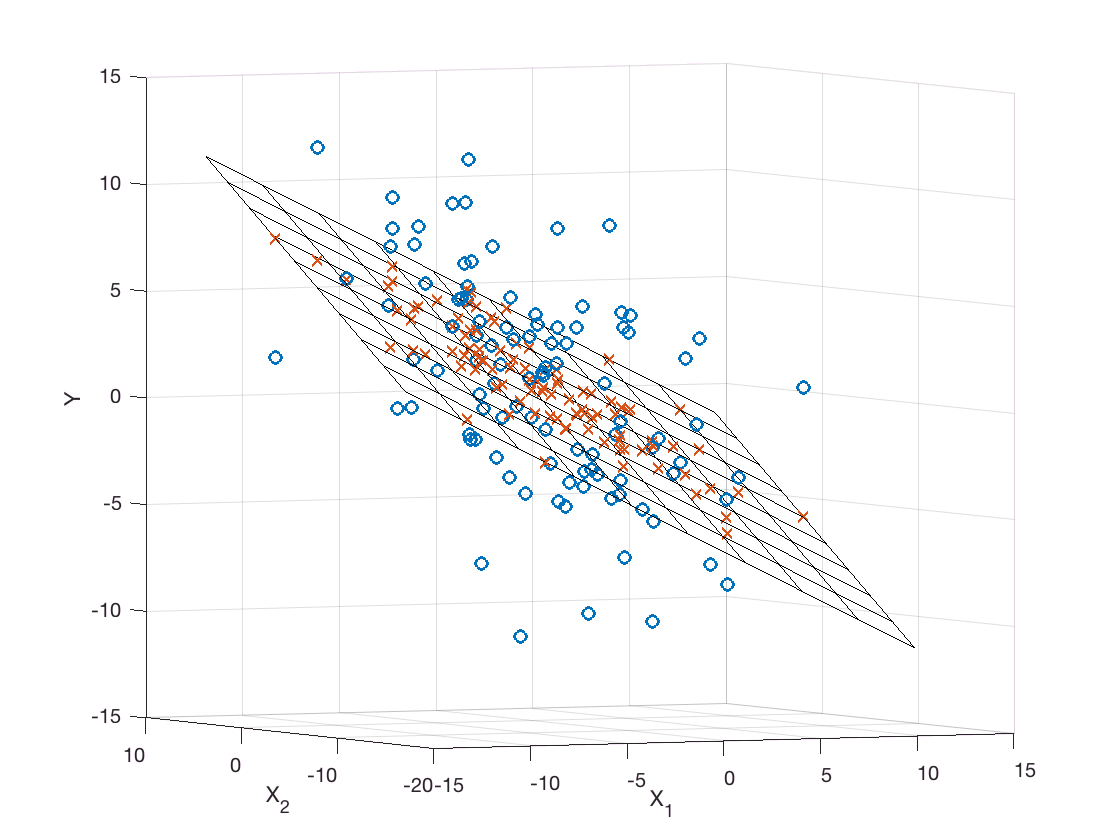

% create the hyperplane of OLS predictions 
xx1 = linspace(min(x1),max(x1),10); 
xx2 = linspace(min(x2),max(x2),10); 
[xx1,xx2] = meshgrid(xx1,xx2);          % xx1 and xx2 become be 10*10
XX = [ones(100,1),xx1(:),xx2(:)];       % xx1(:) converts 10*10 -> 100*1
yhat_plane = XX*betahat;                % 100*1

% plot the hyperplane 
yhat_plane = reshape(yhat_plane,10,10); % 100*1 -> 10*10
s = surf(xx1,xx2,yhat_plane); 
hold off; 

% plot setup
view([-41,3]); % turn the graph
s.FaceAlpha = 0; % how transparent the plane is [0 = no color]
set(gca,'XGrid','on','YGrid','on','ZGrid','on'); 
xlabel('X_1'); ylabel('X_2'); zlabel('Y'); 

Try clicking on the "Rotate" icon in the upper right-hand side of the plot. From the right angle, you can get the red lines to either a) be right inside the blue dots, or b) form up on a straight line. Try changing `sigma_u` to see what happens with the dots. 

## 5: Numerical optimization and visualization

Instead of using the matrix formula, we can estimate the parameters by maximizing the *log likelihood function*. If the model is 


$$y_i = x_i\beta + u_i ,\quad u_i \sim \mathcal{N}(0,\sigma^2_u),$$


then the likelihood function is given by  


$$L(\beta) = \sum_{i=1}^N - \frac{(y_i - x_i\beta)^2}{\sigma^2_u}.$$


[Note: it can be shown that the OLS estimator is actually the closed-form solution to the minimization of $L(\beta)$]

Let us create the likelihood function as an *anonymous function*, taking only a single input. We will put in `sigma_u`; since it is not an input, it will be kept fixed at the value currently in memory (the true value), so we will not be estimating $\sigma_u$ (expanding the code to this is straightforward). 

% since sigma_u is not an input, it is kept fixed 
ll = @(beta) -sum((y - X*beta).^2/sigma_u^2); 

To estimate parameters using Matlab's numerical *minimizer*, `fminunc`. Because it is a minimizer, we will give it the *negative* log likelihood (since the minimum of $-L(\beta)$ is equal to the maximum of $L(\beta)$). We call this anonymous function `f`. Note that `f` takes a single input, which must be a vector (otherwise the matrix product, `X*beta`, to be done in `ll` will fail). 

f = @(beta) -ll(beta); 

Next, we choose starting values for `beta`. We will just start the optimizer in zeros. 

beta0 = [0;0;0];

Finally, we call the optimizer

opt = optimoptions(@fminunc,'algorithm','quasi-newton','maxiter',10000);
thetahat = fminunc(f,beta0,opt)


Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>



thetahat =     0.9672
   -0.5748
    0.2935


And let's plot the found parameters together with the log likelihood: 

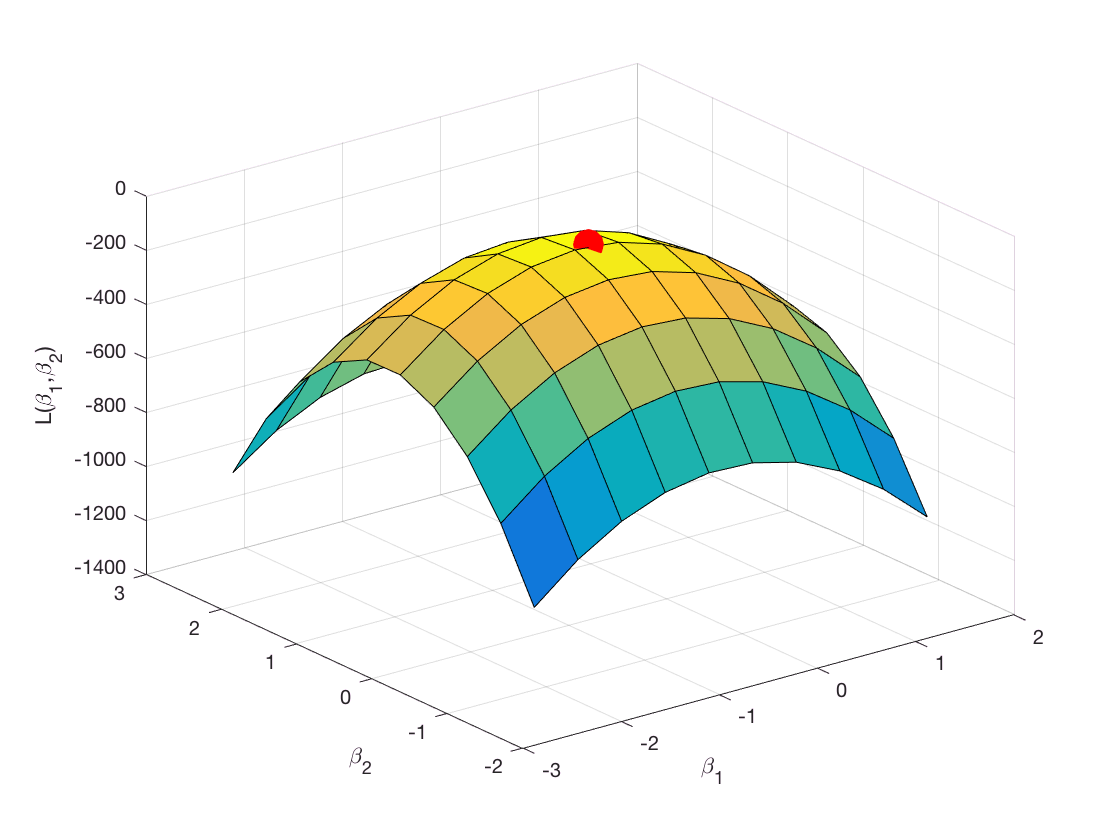

figure(); 
[bb1,bb2,ff] = plot_loglike_around_params(ll,beta_0,beta_1,beta_2,2);
surf(bb1,bb2,ff); % the likelihood function
hold on; 
p = plot3(thetahat(2),thetahat(3),ll(thetahat),'ro','MarkerSize',15,'MarkerFaceColor','r'); % the estimates
hold off;
xlabel('\beta_1'); ylabel('\beta_2'); zlabel('L(\beta_1,\beta_2)'); 

## A non-linear model 

The model we estimated above could easily have been estimated wtih OLS, so in this section we will consider a model which cannot. 


$$y_i = \gamma_0 + \gamma_1 x_{3i}^{\gamma_2} + u_i, \quad u_i \sim \mathcal{N}(0,\sigma^2_u),x_{3i} \ge 0 \forall i.$$


In the bottom of the notebook, you will find a brief discussion of what can and cannot be estimated with OLS. 

% Parameters 
N = 100; 
sigma_u = 1; 
sigma_x = 5; 
gamma_0 = 1; 
gamma_1 = .5; 
gamma_2 = 1.5;  

% Creating variables 
u = sigma_u * randn(N,1); 
x3 = abs(sigma_x*randn(N,1)); % we take abs() to ensure positivity
y2 = gamma_0 + gamma_1*x3.^gamma_2 + u; 

The likelihood function for this model is


$$L(\gamma) = \sum_{i=1}^N -\frac{(y_i - \gamma_0 -\gamma_1 x_{3i}^{\gamma_2} )^2}{\sigma_u^2}.$$


As earlier, we create the likelihood function as an anonymous function, `ll2`, and then create the *negative* likelihood, `f2`, which we pass to `fminunc`. We start the optimizer in the true values. 

ll2 = @(gamma) -sum((y2 - gamma(1) - gamma(2)*x3.^gamma(3)).^2/sigma_u^2); 
f2 = @(gamma) -ll2(gamma); 
gamma0 = [gamma_0;gamma_1;gamma_2]; 
gammahat = fminunc(f2,gamma0,opt)


Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>



gammahat =     0.8458
    0.5724
    1.4486


Below, we will plot the likelihood function together with the estimated parameters. 

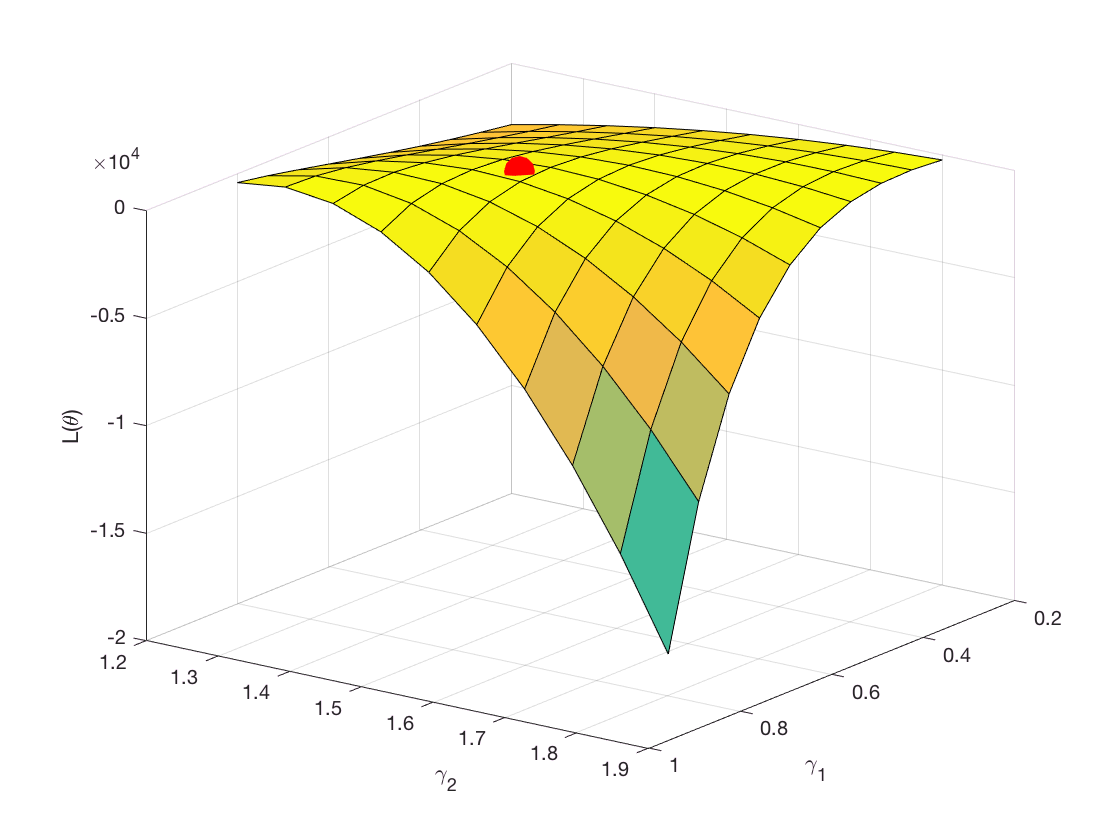

window_width = .3; % how zoomed in around the truth our plot should be 
[gg1,gg2,fff] = plot_loglike_around_params(ll2,gamma_0,gamma_1,gamma_2,window_width); 
surf(gg1,gg2,fff); 
hold on; 
plot3(gammahat(2),gammahat(3),ll2(gammahat),'ro','MarkerSize',15,'MarkerFaceColor','r'); 
hold off;
view([126,23]); % turning the graph 
xlabel('\gamma_1'); ylabel('\gamma_2'); zlabel('L(\theta)'); 

The likelihood function is far more complicated than in the simple linear model. For example, if $\gamma_1=0$ then $\gamma_2$ (the exponent for $x_{3i}$ will have no effect on the predicted outcome. What do you think this means for the likelihood function - do you expect it to be more or less flat when $\gamma_1 \cong 0$? What do you see? Try changing `window_width` to see the likelihood plottet for different parameter values. 

## Appendix: The backslash operator 

The backslash-operator, `\`, tells Matlab that we don't actually need the inverse of `X'*X`; we only need the product of this matrix and the $2\times 1$ vector, `X'*y`. Essentially, writing `A\B` where `A` is an $M\times N$ matrix and `B` is an $N \times 1$ row-vector finds the solution, $x$, to the equation $Ax = B$. Doing so doesn't actualy require us to first find the inverse of `A` and multiply on both sides of the equation. Perhaps you have tried working down to the "echelon form" of a matrix in first-year math; this is what the computer is doing. 

## Appendix: When can we use OLS to estimate a model? 

OLS can be used whenever the model takes the *linear* form, 


$$y_i = \beta_0 + \beta_1 x_{i1} + ... + \beta_K x_{iK} + u_i,\quad \mathrm{E}(u_i|x_{i1},...,x_{iK})=0.$$
 

In this section, we will first discuss how *transformations* can make a seemingly non-linear model linear and thus estimable by OLS, and then how we can add transformations of a regressor to estimate a non-linear relationship using OLS. 

Sometimes, we can have a model which initially does not have this form but where we can *transform* variables to get it on that form anyway so that we can still use OLS, even though the original model was not linear. Consider for example the model 


$$y_i = e^\beta_0 x_{i1}^{\beta_1} x_{i2}^{\beta_2} u_i, \quad u_i \sim \mathrm{IID Lognormal}.$$
 

If we take logs on both sides, we get 


$$\log y_i = \beta_0 + \beta_1 \log x_{i1} + \beta_2 \log x_{i2} + \log u_i.$$
 

Let us introduce the notation 


$$\tilde{y}_i = \beta_0 + \beta_1 \tilde{x}_{i1} + \beta_2 \tilde{x}_{i2} + \tilde{u}_i.$$
 

(i.e. a "tilde" denotes that the variable has been log-transformed). Since we assumed $u_i$ to be IID independent of $x$, in particular $\mathrm{E} (\tilde{u}_i \vert x_{i1},x_{i2}) = 0$ so we can run OLS of $\tilde{y}_i$ on $\tilde{x}_{i1},\tilde{x}_{i2}$ and get consistent estimates from this. 

However, in most cases such a transformation does not exist and so OLS cannot be applied. For instance, in the example we considered, taking logs does not help since $\log (\gamma_0 + \gamma_1 x_{i3}^{\gamma_2} ) \ne \log\gamma_0 + \log(\gamma_1 x_{i3}^{\gamma_2})$. Therefore, in most cases where OLS is applied, the "original" model is only interpreted as a local linear approximation to the truth. 

**Non-linear estimation with OLS? N**ote that one can include all kinds of functions of a regressor, $x_{i1}$, if one were concerned about not capturing the relationship flexibly enough, for example, 


$$y_i = \beta_0 + \beta_1 x_{i1} + \beta_2 x_{i1}^2 + \beta_3 \exp(x_{i1}) + \beta_4 \sin(x_{i1}) + u_i.$$


This function is clearly *non-linear* when we view it as a function of $x_{i1}$, but it is a linear function of the *auxilliary regressors* $(x_{i1},x_{i2}^2,\exp(x_{i1}), \sin(x_{i1}))$. As we add more and more terms, we would therefore expect that our approximation of the true relationship gets better, and we might even be able to approximate the non-linear model. For example, we could take this approach to approximate the non-linear model $y_i = \gamma_0 + \gamma_1 x_{i3} ^ {\gamma_2} + u_i$ using OLS:

X = [ones(size(y,1),1), x3, x3.^2, exp(x3), sin(x3)]; % our matrix of auxilliary regressors 
betahat = (X'*X)\X'*y2

betahat =     0.6475
    0.7611
    0.0891
   -0.0000
   -0.0684


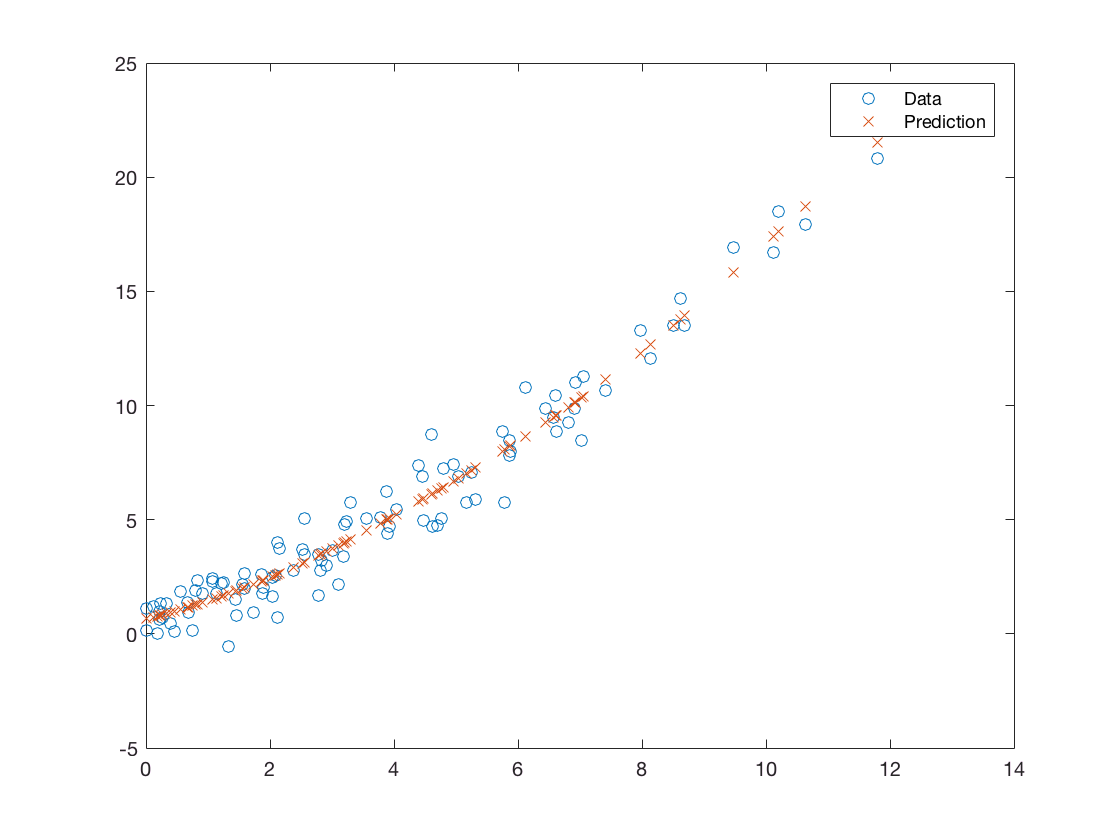

yhat = X*betahat; 

figure; 
plot(x3,y2,'o',x3,yhat,'x'); 

legend('Data','Prediction'); 

**Discussion: **In this case, obviously, the included functions of $x_{i3}$ are somewhat arbitrary and we could keep adding more complex functions. Therefore, we would not apply any interpretation to the individual regressors but instead consider the function as a whole. In contrast, there may be empirical applications where we are willing to make strong assumptions about the functional form of a particular relationship and have a theoretical interpretation for one of the parameters that enter. In this case, we may be forced to use numerical techniques to find our parameter estimates. In some older papers, one may feel the tug of conspiracy theories as to why researchers were willing to make such strong assumptions about a functional form that then conveniently lends itself to OLS estimation (after transformation)... 

## Local functions

This section contains "local function" used throughout the notebook. 

The function `plot_loglike_around_params()` will create a 2-dimensional grid of $10\times10$ for $(\beta_1,\beta_2)$ within $\pm k$ of the given values, `beta_1,beta_2` (user input). The parameter `beta_0` will be kept fixed throughout.  

function [bb1,bb2,ff]=plot_loglike_around_params(ll,beta_0,beta_1,beta_2,k)
bb1_grid = linspace(beta_1-k,beta_1+k,10); 
bb2_grid = linspace(beta_2-k,beta_2+k,10); 
[bb1,bb2] = meshgrid(bb1_grid,bb2_grid); 
ff = nan(10,10); % pre-allocate 

% compute likelihood function for each combination of beta_1,beta_2 
for i1=1:10 
    for i2=1:10 
        beta_grid = [beta_0; bb1_grid(i1); bb2_grid(i2)]; 
        ff(i1,i2) = ll(beta_grid); 
    end
end 

end